## Définition du mouvement

% Vitesse du mobile
vmax = 1;  % m/s

% accélération du mobile
amax = 5; % m/s²

% Position initiale
x_i = 0; % mm
y_i = 0; % mm
theta_i = 0; % rad

% Position finale
x_f = 500; % mm
y_f = 600; % mm
theta_f = 0; % rad

distance = sqrt(x_f^2+y_f^2);
 

## Définition des constantes

% Hauteur mobile
% Largeur mobile
% Rayon du tambour
R_t = 25; % mm
% Temps d'échantillonnage
dt = 0.001 ;

## Définition des lois en trapèze de vitesse

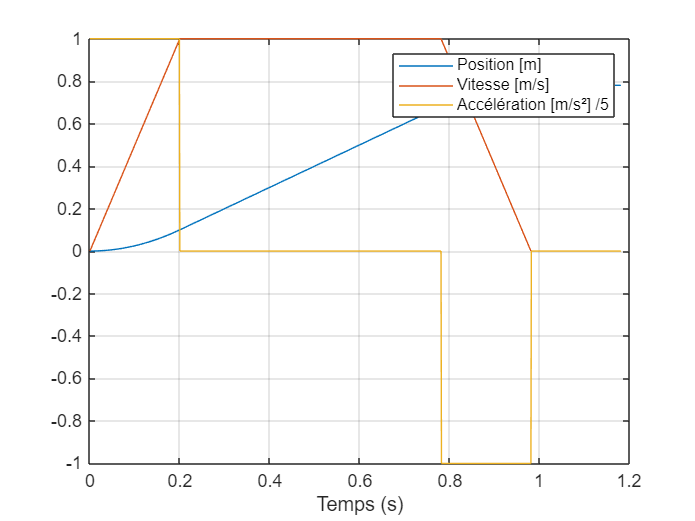

[les_t,les_x,les_v,les_a] = calcule_profil(amax,vmax,distance,dt);
plot(les_t,les_x,les_t,les_v,les_t,les_a/5 )
xlabel('Temps (s)');
grid on;
legend('Position [m]', ...
    'Vitesse [m/s]', ...
    'Accélération [m/s²] /5')

### Tracé de la trajectoire du mobile sur l'espace de travail

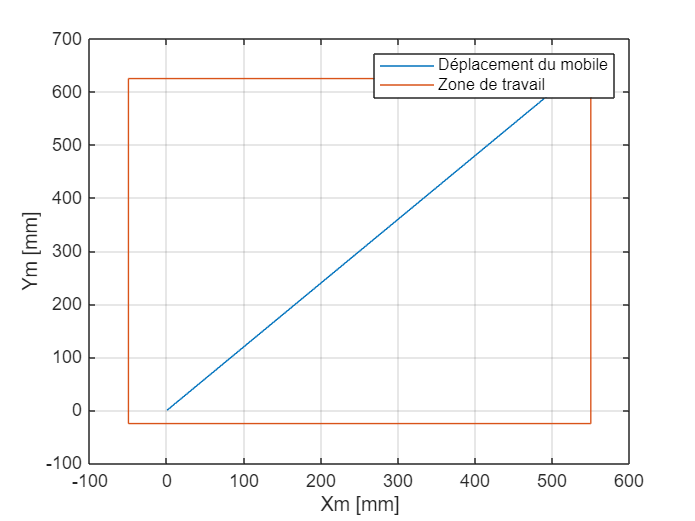

[les_t,les_xm,les_ym] = trajectoire_mobile(x_i,y_i,x_f,y_f,amax,vmax,dt);
% ZONE DE TRAVAIL A VERIFIER
xt = [-50,550,550,-50,-50];
yt = [-25,-25,625,625,-25];

plot(les_xm,les_ym,xt,yt)%,label = "Position mobile");
grid on;
xlabel('Xm [mm]');
ylabel('Ym [mm]');
legend("Déplacement du mobile","Zone de travail")

### Déplacement du mobile

plot(les_t,les_xm, les_t,les_ym )
grid on
xlabel('Temps (s)');
legend("X machine [mm]","Y machine[mm]")

### Tracé de la longueur des câbles

#### Calcul des longueurs

% les_BG = [get_L_phi(les_xm[i],les_ym[i],0,"BG")[1] for i in range(len(les_xm))]
% les_BD = [get_L_phi(les_xm[i],les_ym[i],0,"BD")[1] for i in range(len(les_xm))]
% les_HG = [get_L_phi(les_xm[i],les_ym[i],0,"HG")[1] for i in range(len(les_xm))]
% les_HD = [get_L_phi(les_xm[i],les_ym[i],0,"HD")[1] for i in range(len(les_xm))]

les_bg = [];
les_bd = [];
les_hg = [];
les_hd = [];
for i =1:length(les_xm)
    [bg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BG");
    [bd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BD");
    [hg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HG");
    [hd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HD");
    les_bg(end+1) = bg;
    les_bd(end+1) = bd;
    les_hg(end+1) = hg;
    les_hd(end+1) = hd;
end

#### Tracé en mm

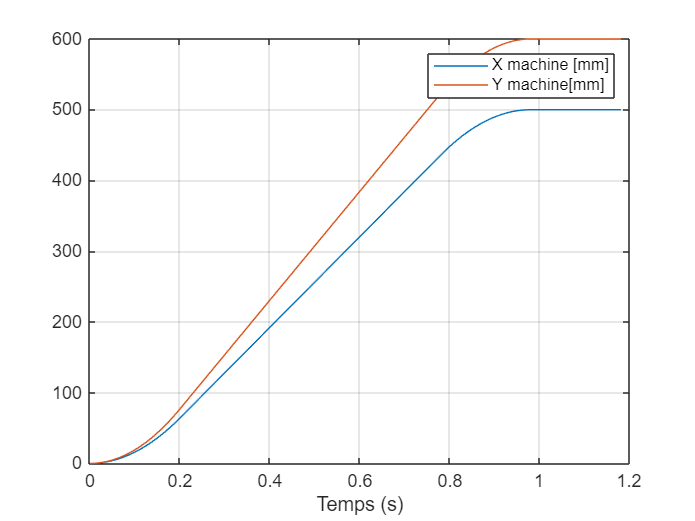

tiledlayout(2,2)

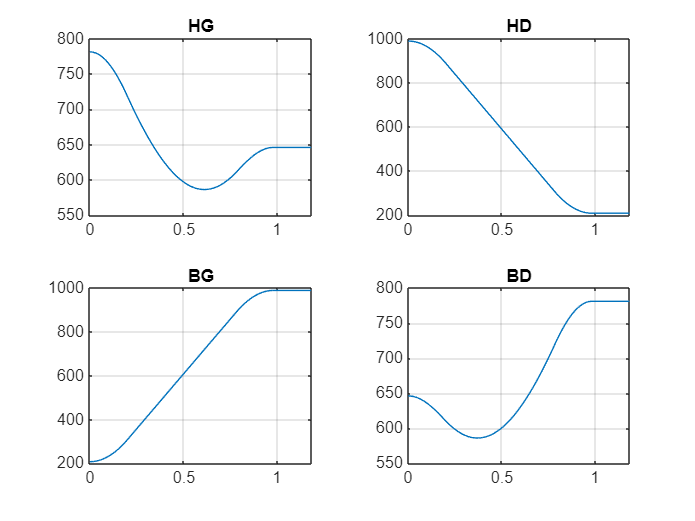

nexttile
plot(les_t,les_hg)
grid on
title("HG")

nexttile
plot(les_t,les_hd)
grid on
title("HD")

nexttile
plot(les_t,les_bg)
grid on
title("BG")

nexttile
plot(les_t,les_bd)
grid on
title("BD")

#### Conversion en points

les_hg_qc = 8192*les_hg/R_t/2/pi;
les_hd_qc = 8192*les_hd/R_t/2/pi;
les_bg_qc = 8192*les_bg/R_t/2/pi;
les_bd_qc = 8192*les_bd/R_t/2/pi;

% tiledlayout(2,2)
% nexttile
% plot(les_t,les_hg_qc)
% grid on
% title("HG")
% 
% nexttile
% plot(les_t,les_hd_qc)
% grid on
% title("HD")
% 
% nexttile
% plot(les_t,les_bg_qc)
% grid on
% title("BG")
% 
% nexttile
% plot(les_t,les_bd_qc)
% grid on
% title("BD")

## Import de données expérimentales

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [16, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Temps", "TrimNonNumeric", true);
opts = setvaropts(opts, "Temps", "ThousandsSeparator", ",");

% Import the data
les_hd_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_HD.csv", opts);

% Clear temporary variables
clear opts

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts2.DataLines = [16, Inf];
opts2.Delimiter = ";";

% Specify column names and types
opts2.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, "Temps", "TrimNonNumeric", true);
opts2 = setvaropts(opts2, "Temps", "ThousandsSeparator", ",");

% Import the data
les_hg_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_HG.csv", opts2);

% Clear temporary variables
clear opts2

% Set up the Import Options and import the data
opts3 = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts3.DataLines = [16, Inf];
opts3.Delimiter = ";";

% Specify column names and types
opts3.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts3.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts3.ExtraColumnsRule = "ignore";
opts3.EmptyLineRule = "read";

% Specify variable properties
opts3 = setvaropts(opts3, "Temps", "TrimNonNumeric", true);
opts3 = setvaropts(opts3, "Temps", "ThousandsSeparator", ",");

% Import the data
les_bd_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_BD.csv", opts3);

% Clear temporary variables
clear opts3

% Set up the Import Options and import the data
opts4 = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts4.DataLines = [16, Inf];
opts4.Delimiter = ";";

% Specify column names and types
opts4.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts4.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts4.ExtraColumnsRule = "ignore";
opts4.EmptyLineRule = "read";

% Specify variable properties
opts4 = setvaropts(opts4, "Temps", "TrimNonNumeric", true);
opts4 = setvaropts(opts4, "Temps", "ThousandsSeparator", ",");

% Import the data
les_bg_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_BG.csv", opts4);

% Clear temporary variables
clear opts4

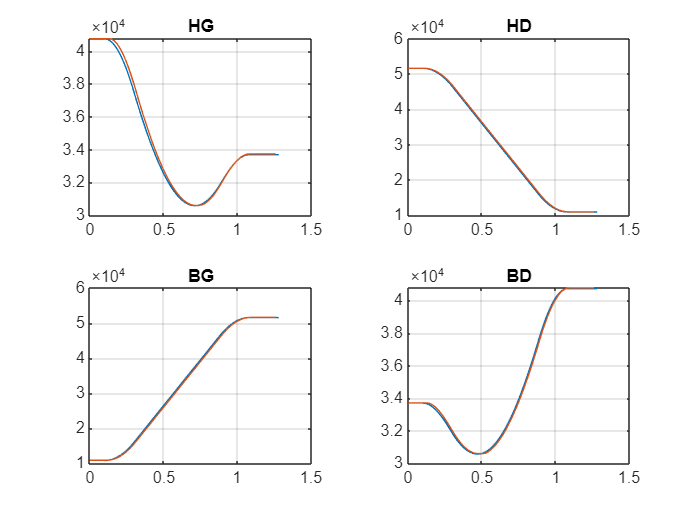

dec_t = 0.1;
tiledlayout(2,2)
nexttile
%plot(les_t,les_hg_qc,les_hg_qc_mes.Temps/1000,les_hg_qc,les_hg_qc_mes.PositionAxe)
plot(les_t+dec_t,les_hg_qc,les_hg_qc_mes.Temps(2:end-10)/10000,les_hg_qc_mes.PositionAxe(2:end-10))
grid on
title("HG")

nexttile
plot(les_t+dec_t,les_hd_qc,les_hd_qc_mes.Temps(2:end-10)/10000,les_hd_qc_mes.PositionAxe(2:end-10))
grid on
title("HD")

nexttile
plot(les_t+dec_t,les_bg_qc,les_bg_qc_mes.Temps(2:end-10)/10000,les_bg_qc_mes.PositionAxe(2:end-10))
grid on
title("BG")

nexttile
plot(les_t+dec_t,les_bd_qc,les_bd_qc_mes.Temps(2:end-10)/10000,les_bd_qc_mes.PositionAxe(2:end-10))
grid on
title("BD")

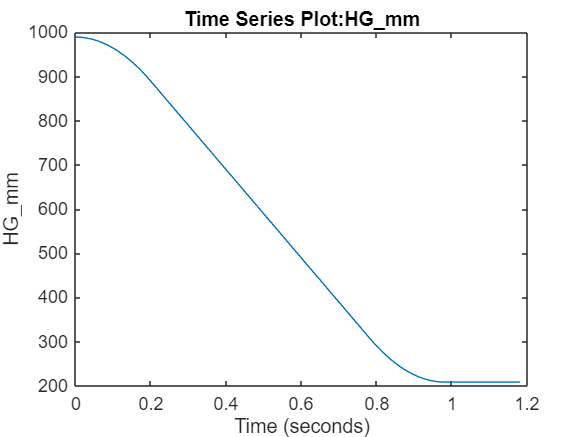

figure

ts = timeseries(les_hd,les_t,"Name","HG_mm");
plot(ts)

max(les_hd)

ans = 989.3068


L_HD = les_hd(1)

L_HD = 989.3068

L_HG = les_hg(1)

L_HG = 781.2821

L_BD = les_bd(1)

L_BD = 646.1061

var = [L_HD,L_HG,L_BD]

var =   989.3068  781.2821  646.1061


disp("ici")

ici



fff = modele_direct([0,0,0,0,0,0],var)

fff =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000



disp("la")

la


fun = @(x)@modele_direct(x,var);

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

% 
 
x0 = [0,0,0,0,0,0];
x = fsolve(fun,x0)

fun = @modele_direct;

x0 = [0,0,0,0,0,0];
x = fsolve(fun,x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     3.7442  -20.5892    0.0091    0.9171    1.7040   -0.2409


oooo = -364.3068

ans = -364.3068

F(1) = X_HD - R_P * sin(phi_hd)-L_HD*cos(phi_hd) - L_M/2 * cos(theta)+H_M/2*sin(theta) - X_M

F =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000


F(2) = Y_HD + R_P * cos(phi_hd)-L_HD*sin(phi_hd) - L_M/2 * sin(theta)-H_M/2*cos(theta) - Y_M

F =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000



F(3) = X_HG + R_P * sin(phi_hg)-L_HG*cos(phi_hg) + L_M/2 * cos(theta)+H_M/2*sin(theta) - X_M

F =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000


F(4) = Y_HG - R_P * cos(phi_hg)-L_HG*sin(phi_hg) + L_M/2 * sin(theta)-H_M/2*cos(theta) - Y_M

F =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000



F(5) = X_BD - R_P * sin(phi_bd)-L_BD*cos(phi_bd) - L_M/2 * cos(theta)+H_M/2*sin(theta) - X_M

F =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000


F(6) = Y_BD - R_P * cos(phi_bd)-L_BD*sin(phi_bd) - L_M/2 * sin(theta)+H_M/2*cos(theta) - Y_M

F =  -364.3068  775.0000 -906.2821  725.0000  -21.1061 -175.0000
